syms kappa tau

T(1,:) = [1 0 0]

T =     1.0000         0         0
    1.0000    0.0377         0
    0.9986    0.0754         0
    0.9957    0.1130         0
    0.9915    0.1505         0
    0.9858    0.1879         0
    0.9787    0.2251         0
    0.9702    0.2619         0
    0.9604    0.2985         0
    0.9491    0.3347         0


N(1,:) = [0 1 0]

N =          0    1.0000         0
   -0.0377    1.0000         0
   -0.0754    0.9986         0
   -0.1130    0.9957         0
   -0.1505    0.9915         0
   -0.1879    0.9858         0
   -0.2251    0.9787         0
   -0.2619    0.9702         0
   -0.2985    0.9604         0
   -0.3347    0.9491         0


B(1,:) = [0 0 1]

B =      0     0     1
     0     0     1
     0     0     1
     0     0     1
     0     0     1
     0     0     1
     0     0     1
     0     0     1
     0     0     1
     0     0     1



A = [0 kappa 0;-kappa 0 tau;0 -tau 0]

$$A = \left(\begin{array}{ccc} 0 & \kappa & 0\\ -\kappa & 0 & \tau \\ 0 & -\tau & 0 \end{array}\right)$$


frenetSerret =@(kappa,tau,T,N,B) [0 kappa 0;-kappa 0 tau;0 -tau 0]*[T;N;B]

frenetSerret = function_handle with value:
    @(kappa,tau,T,N,B)[0,kappa,0;-kappa,0,tau;0,-tau,0]*[T;N;B]



s = linspace(0,150,200)

s =          0    0.7538    1.5075    2.2613    3.0151    3.7688    4.5226    5.2764    6.0302    6.7839    7.5377    8.2915    9.0452    9.7990   10.5528   11.3065   12.0603   12.8141   13.5678   14.3216   15.0754   15.8291   16.5829   17.3367   18.0905   18.8442   19.5980   20.3518   21.1055   21.8593   22.6131   23.3668   24.1206   24.8744   25.6281   26.3819   27.1357   27.8894   28.6432   29.3970   30.1508   30.9045   31.6583   32.4121   33.1658   33.9196   34.6734   35.4271   36.1809   36.9347


kappa = .05*ones(size((s)))

kappa =     0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500



x = zeros([length(s),3]);

for i = 2:length(s)
    TNB_prime = frenetSerret(kappa(i),0,T(i-1,:),N(i-1,:),B(i-1,:));

    % can't assume this stays constant,  
    % different discretization schemes might use variable spacing
    delta_s = s(i) - s(i-1);

    T(i,:) = makeUnitVector(T(i-1,:) + TNB_prime(1,1:3)*delta_s);
    N(i,:) = makeUnitVector(N(i-1,:) + TNB_prime(2,1:3)*delta_s);
    B(i,:) = makeUnitVector(B(i-1,:) + TNB_prime(3,1:3)*delta_s);

    x(i,:) = x(i-1,:) + delta_s .* T(i,:);

end
a = "😮"

a = "😮"

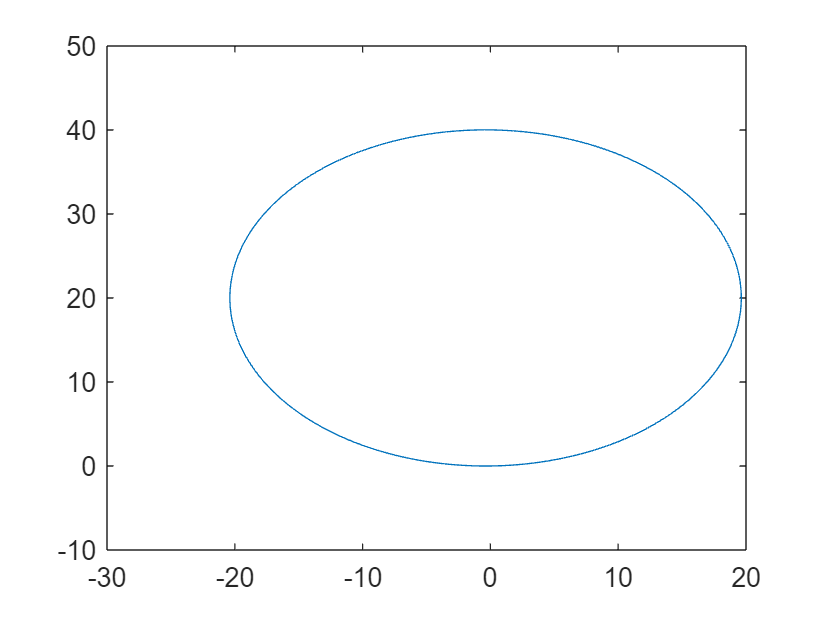


plot(x(:,1),x(:,2))

function u = makeUnitVector(v)

u = v./norm(v);

end

